# **Marginal Analyses:** *A Guide*

The code in this live-script references functions contained in `analyze.marg`

  % Click here to run analyses

Many of the population-level analyses that are described in assessments of neurophysiological spiking population dynamics seek to interpret not necessarily the mean firing rate, which indeed co-varies most strongly with specific elements of behavior, but rather, the unaccounted **variance **in underlying processes (sometimes referred to as *factors*), which might otherwise be better explained when viewed in covariance of overall population "dispersion" under certain task-specific conditions. This script tries to walk through that process in a sensible way.

### Initialize `marg` Data

#### `Clear workspace & load data (if needed)`

clearvars -except T
if exist('T','var')==0
   % note that `'rate_table_default_matfile'` is the smaller table
   % it does not necessarily contain all Alignments etc. (just to save time
   % on loading). It may be necessary to load the other, larger `'T.mat'`
   % file, which doesn't have _default.mat apprended on the end of the
   % filename.
   load(defaults.files('rate_table_default_matfile'),'T');
end

#### Reduce table to working subset, `M`

M = analyze.marg.get_subset(T);

# **Remove Relevant Marginalizations**

### Subtract group means in a principled way

We expect there to be large, striking differences in the observed neurophsyiological spiking time-series, with this being unsurprising for the following marginalizations: 

- `Group `(we expect a difference between *Ischemic* vs. *Intact *rats)

- `Rat` (we expect a *random *within-rat difference simply due to different combination of recording channels etc.)

- `Area `(we expect a difference on the basis of *Premotor *vs. *Motor *area)

- `ICMS `(motor representation, such as *Forelimb* vs. *Whiskers*)

- `Channel `(a huge difference for individual channels)

Note that it is likely that even mean-subtraction **across sessions **would have a substantial impact!

Therefore, we can optionally add the following marginalization filter:

- `BlockID` (recording session)

marginalizations = {'AnimalID','BlockID','Area','Channel','Alignment'};
  % Click here to run analyses

#### Create marginalized dataset

S = analyze.marg.subtract_rat_means(M,marginalizations);

### View example of mean-subtracted rates

Click **Plot Rates **once you have selected the desired *Alignment *and *Outcome *parameters.

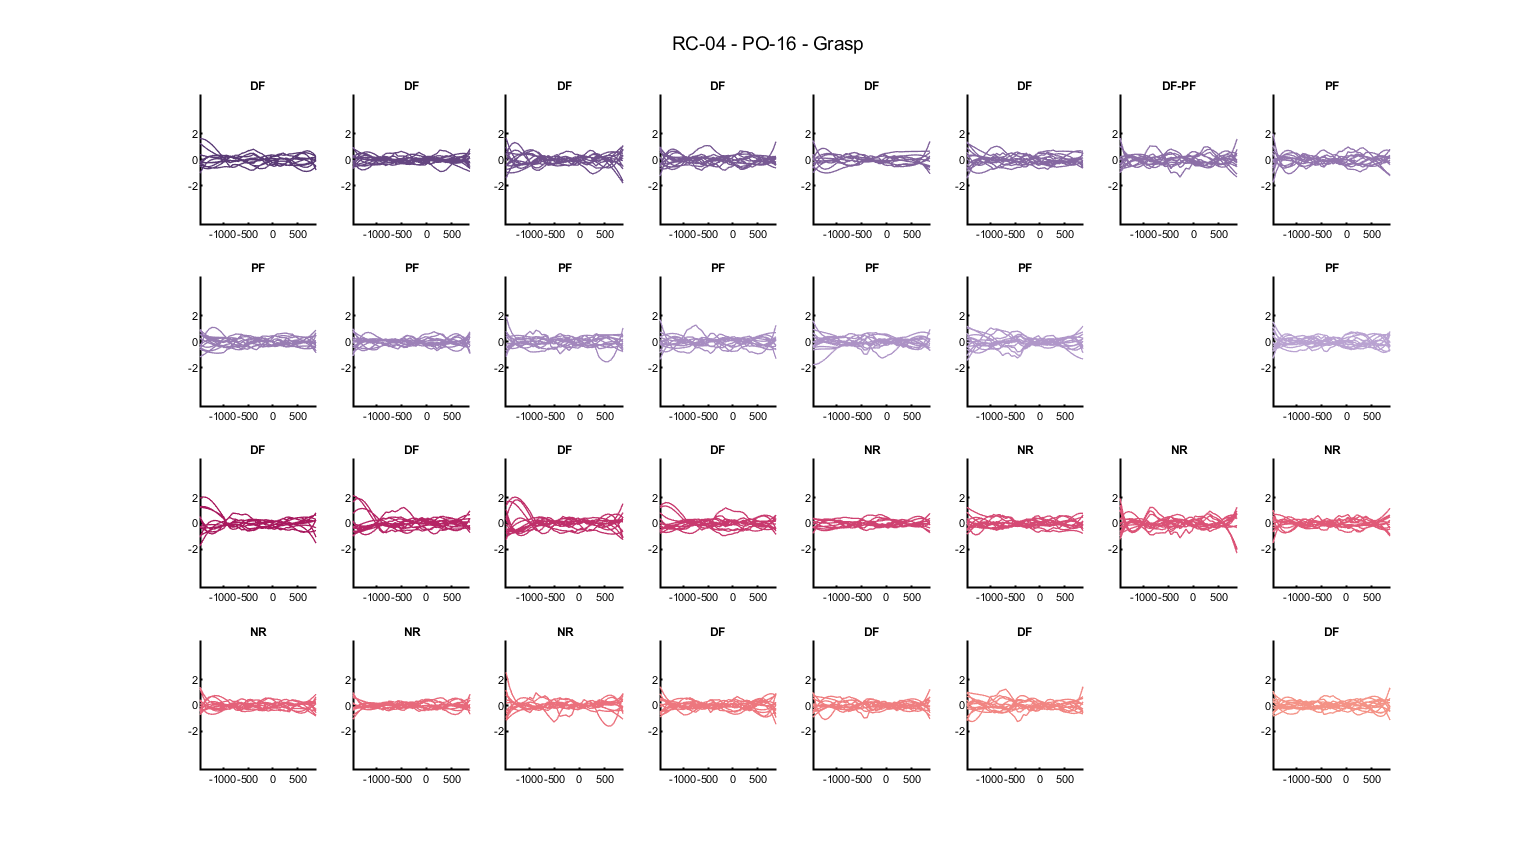

animal = 'RC-04';
align_event = 'Grasp';
outcome = {'Successful','Unsuccessful'};
min_n_trials = 10;
save_fig = false; % Auto-saves the figure, if ticked
  % This will change `small-s` (table) each time you click it

% % Survey of some that I've looked at % %
% RC-21 - PO-14 - Grasp: looks good in jPCA on Plane-1
% RC-43 - PO-24 - Grasp: looks good in jPCA on Plane-1
% RC-05 - PO-08 - Grasp: not as strong jPCA structure on Plane-1
% RC-02 - PO-17 - Grasp: not as strong jPCA structure on Plane-1
% RC-04 - PO-16 - Grasp: not as strong jPCA structure on Plane-1

[fig_by_Channel,s] = analyze.rec.plot_rate(...
    utils.filterByNTrials(S,min_n_trials,outcome,'AnimalID',animal),... 
    align_event,outcome,save_fig,1);

This figure produces subplots for **all trials **of a **single Block**. Each subplot represents a different channel. The top two rows represent normalized spike rates on channels that are in Caudal Forelimb Area (CFA; rat M1 homolog) that is ipsilateral to the forelimb retrieving the pellet. The bottom two rows represent normalized spike rates on channels that are in Rostral Forelimb Area (RFA; rat PM homolog) contralateral to the forelimb retrieving the pellet. Time is represented on the x-axis in milliseconds. The bold text above each subplot indicates the approximate intracortical microstimulation (ICMS) co-registration from a mapping procedure done just prior to the insertion of the microwire arrays. It follows the key:

- **Distal Forelimb **(DF)

- **Proximal Forelimb **(PF)

- **Distal & Proximal Forelimb **(DF-PF)

- **No Response **(NR; 80 uA maximum current)

- **Other **(O; e.g. Trunk, Vibrissae, Mouth, etc.)

Verify that the mean-subtracted outcomes make sense; **the largest "modulated" component should be the task-aligned one. **Since we do not typically see "traditionally" coherent task-related fluctuations, particularly around the **0-ms** task alignment, it looks like we correctly subtracted the mean. You can see if there is a difference by toggling the check-box below.

if false
    [fig_by_Channel_orig] = analyze.rec.plot_rate(M(ismember(M.RowID,s.RowID),:),...
        align_event,outcome,save_fig,1); %#ok<UNRCH> 
end

# **Apply Population-Level Analysis**

Using our marginalized dataset, we can now apply population-level analysis. A principled approach is detailed in (cite), which describes **jPCA, **a method that attempts to assess the strength of *rotatory dynamics *present under the assumption that the population dynamics are the result of factors governed in an oscillatory fashion, which is captured by a system of differential equations as:


$$\delta X=XM_{\textrm{skew}}$$


Where $M_{\textrm{skew}}$ is constrained to be skew-symmetric during the optimization procedure (a least-squares minimization). The recovered fit should then be compared to $M_{\textrm{best}}$, which is the optimal solution in the least-squares sense. If the fits are *comparable *(and that part can be nebulous; in general, it would seem that you want the top pairs of eigenvectors to capture 20-40% of the observed data variance as a seeming rule of thumb).

## Organize data for `jPCA` code

*Note that all code in *`analyze.jPCA`* is based on code kindly provided by John P. Cunningham & Mark Churchland; it has been changed slightly from the original format to accomodate some optional parameters for visualization purposes, and the documentation is changed to reflect notes as I was learning the material.*

#### We will use the (small-m) matrix that we inspected rates for above

 
[Data,J,JID] = analyze.jPCA.convert_table(s,...
    'Alignment',align_event,...
    'Outcome',outcome);


	->	Table conversion for jPCA complete.


### Verify `Data` exported as intended

Once the `Data` struct has been exported for `jPCA`, plot one of the exported trials just to make sure that filtering/interpolating didn't mess it up too much.

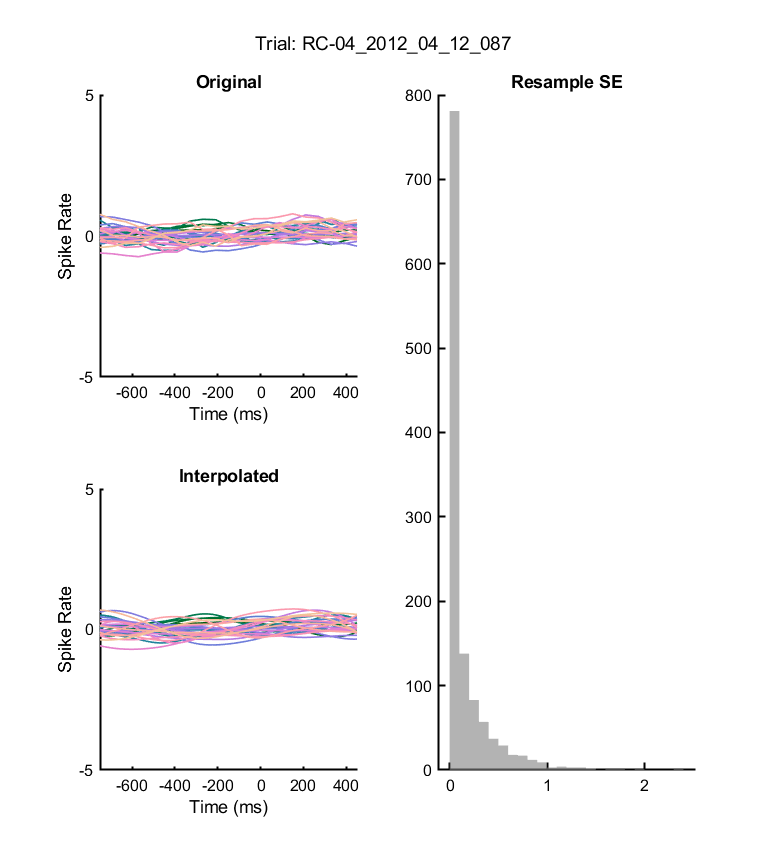

 
fig = analyze.marg.plot_trial_to_double_check(Data,J);

In these panels, the top-left shows the "Original" spike rates (after an initial smoothing step, and whatever other processing has been applied, as shown in `J.Properties.UserData.Processing`. We need to visually inspect to make sure that the filtering and smoothing applied for the interpolation and export to `jPCA` to get the correct timescale to improve our nominal estimate of the derivative at each time-sample is **not causing the data to change drastically**. The distribution of errors (*right*) shows that, for a minority of the samples, there actually is a substantial change induced by this smoothing and interpolation step; however, the majority of the sample differences are very close to zero (and some of the error should be accounted for by non-exact matches of interpolated times compared to the "closest" original time, so that differences could be taken to begin with). 

#### Recover `jPCA` projections and summary structure

eigenvalues of Mskew: 
                  0.015i     -0.015i 
                  0.011i     -0.011i 
                  0.007i     -0.007i 
                  0.003i     -0.003i 
                  0.002i     -0.002i 
% R^2 for Mbest (all 10 dims):   0.17
% R^2 for Mskew (all 10 dims):   0.15  <<---------------
% R^2 for Mbest (primary 2D plane):   0.33
% R^2 for Mskew (primary 2D plane):   0.29  <<---------------


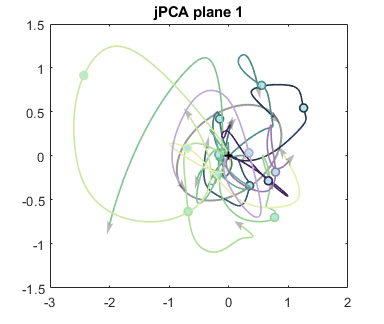

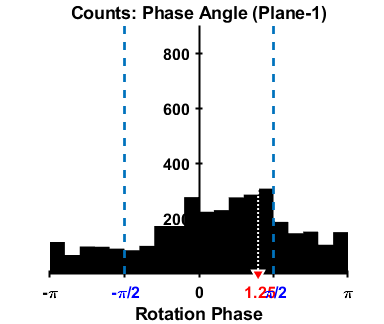

[Projection,Summary] = analyze.jPCA.jPCA(Data);

**Top: **The panel shows the selected **jPCA plane**, which is spanned by a pair of basis vectors in the linear mapping of the data such that it is best fit to its own (time) derivative. The least-squares minimization procedure that recovers this matrix is constrained such that the algorithm must recover a skew-symmetric transformation matrix, which by definition should have pairs of complex-conjugate eigenvectors indicative of a "rotatory subspace" within the neuronal population time-series dynamics. Ideally, each "rosette" arrow (an individual trial)

**Bottom: **The distribution of phase angle differences between the position in jPCA-plane-space and the corresponding "velocity" of the neural trajectory at that position in jPCA-plane-space. A distribution centered about pi or -pi indicates an offset of 90 degrees between the two phase angles indicates "perfect" rotatory structure (e.g. circles) within the subspace.